# Analityczne wyznaczanie ekstremów funkcji wielu zmiennych

syms x_1 x_2
f=x_2*exp(-x_1^2-x_2^2)

$$f = x_{2}\,{\mathrm{e}}^{-{x_{1}}^{2}-{x_{2}}^{2}}$$

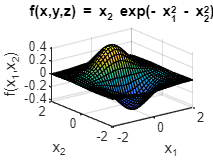


fsurf(f,[-2, 2])
title(['f(x,y,z) = ' texlabel(f)])
xlabel('x_1'), ylabel('x_2'), zlabel('f(x_1,x_2)')


% Pierwsze pochodne cząstkowe
grad=gradient(f)

$$grad = \left(\begin{array}{c} -2\,x_{1}\,x_{2}\,{\mathrm{e}}^{-{x_{1}}^{2}-{x_{2}}^{2}}\\ {\mathrm{e}}^{-{x_{1}}^{2}-{x_{2}}^{2}}-2\,{x_{2}}^{2}\,{\mathrm{e}}^{-{x_{1}}^{2}-{x_{2}}^{2}} \end{array}\right)$$

%grad = subs(grad, x_1, 2)

$$grad = \left(\begin{array}{c} -4\,x_{2}\,{\mathrm{e}}^{-{x_{2}}^{2}-4}\\ {\mathrm{e}}^{-{x_{2}}^{2}-4}-2\,{x_{2}}^{2}\,{\mathrm{e}}^{-{x_{2}}^{2}-4} \end{array}\right)$$

%grad = subs(grad, x_2, 1)

$$grad = \left(\begin{array}{c} -4\,{\mathrm{e}}^{-5}\\ -{\mathrm{e}}^{-5} \end{array}\right)$$

%vpa(grad)

$$ans = \left(\begin{array}{c} -0.026951787996341868386544193692594\\ -0.0067379469990854670966360484231484 \end{array}\right)$$

% miejsca zerowania się pierwszych pochodnych cząstkowych
extrem=solve(grad==0)

Error using sym/solve (line 266)
Specify the variable to solve for.

pot_points = [extrem.x_1 extrem.x_2]

J=jacobian(grad, [x_1, x_2])
H=hessian(f,[x_1,x_2])

% Podstawienie do macierzy Hessego (drugiej pochodnej punkcji) wartości
% potencjalnych punktów w których mogą wystąpić ekstrema - miejsc zerowania
% się pierwszych pochodnych (macierz pot_points)
H_1=subs(H, [x_1 x_2], [pot_points(1,1), pot_points(1,2)])
H_2=subs(H, [x_1 x_2], [pot_points(2,1), pot_points(2,2)])

% Wyznaczniki
detH_1=det(H_1)
detH_2=det(H_2)
detH_1=double(detH_1)
detH_2=double(detH_2)

eks_point1 = double(pot_points(1,:))
eks_point2 = double(pot_points(2,:))

% Sprawdzanie czy minimum czy maksimum
H11_p1 = double(H_1(1,1))
% Punkt p1 jest minimum, bo H_11 > 0
H11_p2 = double(H_2(1,1))
% Punkt p2 jest maksimum, bo H_11 < 0


Jeśli pochodna czątkowa = 0 i wyznacznik Hesjanu jest dodatni, to f ma w tym punkcie ekstremum

% W celu określenia wypukłości musimy zbadać określoność macierzy Hessego
% (przy pomocy kryterium Sylwestera)

minor1 = solve(H(1,1) > 0, [x_1 x_2], 'Real', true)
minor1.x_1
minor1.x_2
fsurf(H(1,1) >= 0, [-2, 2])

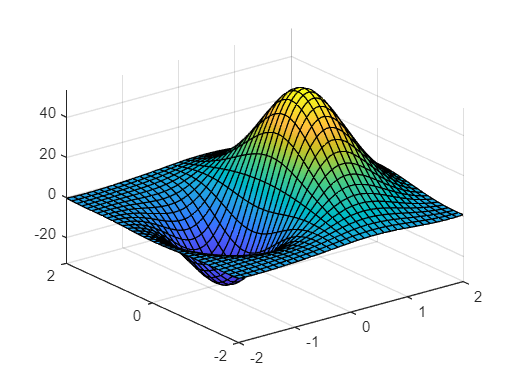

f2 = 0.3*x_1+0.1*x_2+(-3.5+0.5*x_1^2+0.5*x_2^2)^2+100*x_1 * exp(-x_1^2 - x_2^2);
fsurf(f2, [-2 2])

% Pierwsze pochodne cząstkowe
grad2=gradient(f2)

$$grad2 = \begin{array}{l} \left(\begin{array}{c} 100\,\sigma_{1}-200\,{x_{1}}^{2}\,\sigma_{1}+2\,x_{1}\,\left(\frac{{x_{1}}^{2}}{2}+\frac{{x_{2}}^{2}}{2}-\frac{7}{2}\right)+\frac{3}{10}\\ 2\,x_{2}\,\left(\frac{{x_{1}}^{2}}{2}+\frac{{x_{2}}^{2}}{2}-\frac{7}{2}\right)-200\,x_{1}\,x_{2}\,\sigma_{1}+\frac{1}{10} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-{x_{1}}^{2}-{x_{2}}^{2}} \end{array}$$


% miejsca zerowania się pierwszych pochodnych cząstkowych
extrem2 = solve(grad2==0)

extrem2 = struct with fields:
    x_1: 2.5972108266993937373276830669093
    x_2: 0.69762334627548936016766205597833


pot_points2 = [extrem2.x_1 extrem2.x_2]

$$pot\_points2 = \left(\begin{array}{cc} 2.5972108266993937373276830669093 & 0.69762334627548936016766205597833 \end{array}\right)$$